On a attenuation waveform, we will mark the max and min points, and show their coordinates.

clear
a = 0.2;    % attenuation coefficient 
w = 3;    % oscillation frequency
t = 0:0.01:20;    % sampling points


Oscillation-attenuation function : $f\left(t\right)=\text{ }e^{−a\text{ }t} sin\left(w\text{ }t\right)$

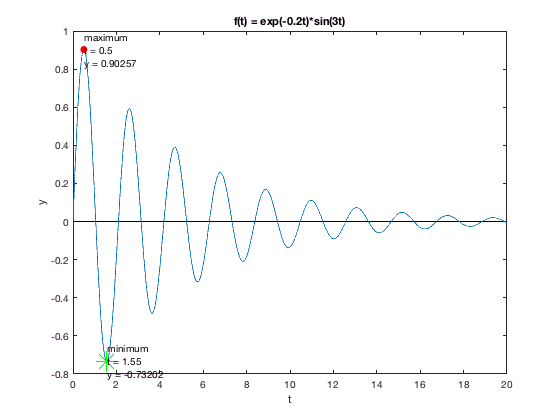

y = exp(-a*t).*sin(w*t);
[y_max, i_max] = max(y);    % Find the element with max value
[y_min, i_min] = min(y);    % Find the element with min value
tmax_text = ['t = ', num2str(t(i_max))];    % Retrieve the horizonal coordinate at max point, and convert it to string
ymax_text = ['y = ', num2str(y_max)];        % Retrieve the vertical coordinate at max point, and convert it to string
max_text = char('maximum', tmax_text, ymax_text);

tmin_text = ['t = ', num2str(t(i_min))];
ymin_text = ['y = ', num2str(y_min)];
min_text = char('minimum', tmin_text, ymin_text);

% Plot the base line
plot(t, zeros(size(t)), 'k');
hold on
% plot the oscillation attenuation waveform
plot(t, y);

% Mark the peak point
plot(t(i_max), y_max, 'r.', 'MarkerSize', 20);
text(t(i_max), y_max, max_text);

plot(t(i_min), y_min, 'g*', 'MarkerSize', 20);
text(t(i_min), y_min, min_text);

% Show the coordinate name
waveform_title = ['f(t) = exp(-', num2str(a), 't)*sin(', num2str(w), 't)'];
title(waveform_title);
xlabel('t');
ylabel('y');
hold off